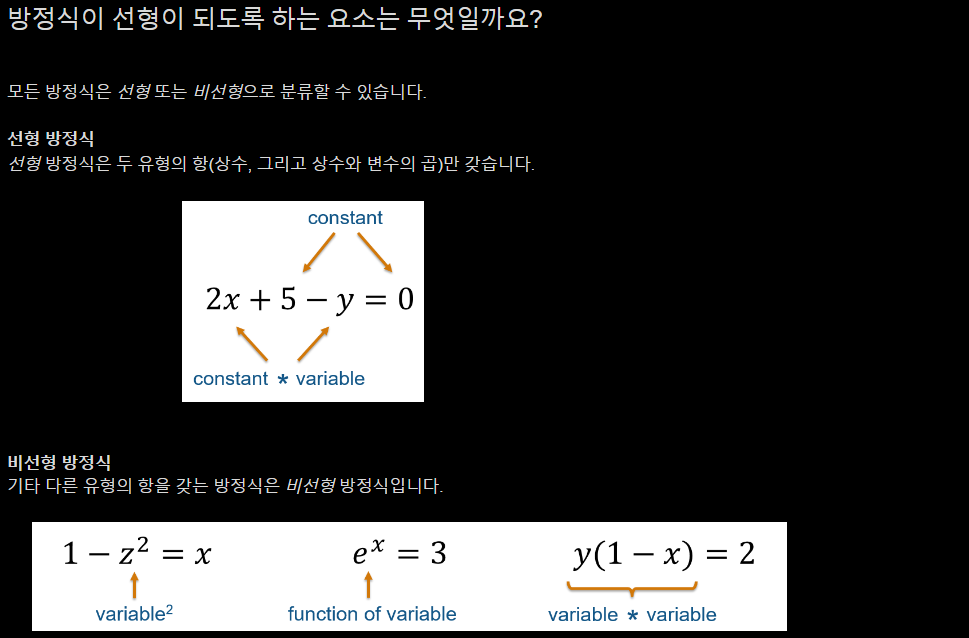

# Visualizing Linear Systems

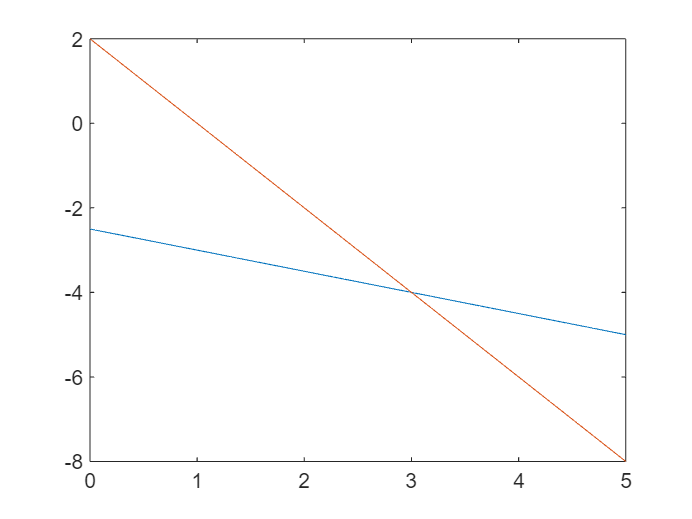

x = linspace(0,5,100);
y1 = -0.5*x-2.5;
plot(x,y1)
hold on
y2 = -2*x+2;
plot(x,y2)
hold off

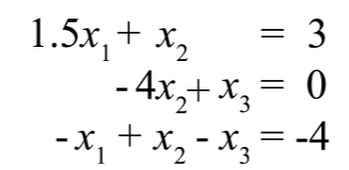우변에는 상수항, 좌변에는 same order로 변수들

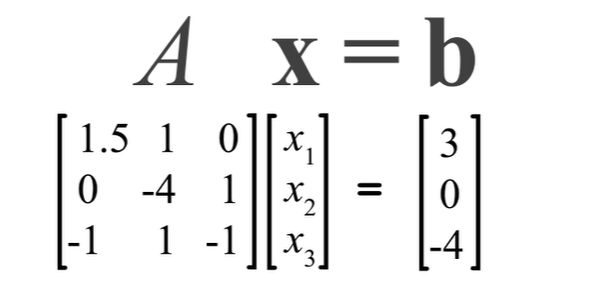

# Plot and Solve a System of Linear Equations

x = linspace(0,3,100)

x =          0    0.0303    0.0606    0.0909    0.1212    0.1515    0.1818    0.2121    0.2424    0.2727    0.3030    0.3333    0.3636    0.3939    0.4242    0.4545    0.4848    0.5152    0.5455    0.5758    0.6061    0.6364    0.6667    0.6970    0.7273    0.7576    0.7879    0.8182    0.8485    0.8788    0.9091    0.9394    0.9697    1.0000    1.0303    1.0606    1.0909    1.1212    1.1515    1.1818    1.2121    1.2424    1.2727    1.3030    1.3333    1.3636    1.3939    1.4242    1.4545    1.4848


y1 = 6-x

y1 =     6.0000    5.9697    5.9394    5.9091    5.8788    5.8485    5.8182    5.7879    5.7576    5.7273    5.6970    5.6667    5.6364    5.6061    5.5758    5.5455    5.5152    5.4848    5.4545    5.4242    5.3939    5.3636    5.3333    5.3030    5.2727    5.2424    5.2121    5.1818    5.1515    5.1212    5.0909    5.0606    5.0303    5.0000    4.9697    4.9394    4.9091    4.8788    4.8485    4.8182    4.7879    4.7576    4.7273    4.6970    4.6667    4.6364    4.6061    4.5758    4.5455    4.5152


plot(x,y1)
y2 = 2 + 3*x

y2 =     2.0000    2.0909    2.1818    2.2727    2.3636    2.4545    2.5455    2.6364    2.7273    2.8182    2.9091    3.0000    3.0909    3.1818    3.2727    3.3636    3.4545    3.5455    3.6364    3.7273    3.8182    3.9091    4.0000    4.0909    4.1818    4.2727    4.3636    4.4545    4.5455    4.6364    4.7273    4.8182    4.9091    5.0000    5.0909    5.1818    5.2727    5.3636    5.4545    5.5455    5.6364    5.7273    5.8182    5.9091    6.0000    6.0909    6.1818    6.2727    6.3636    6.4545


hold on
plot(x, y2)

선형 방정식 정의

A = [1 1;-3 1]

A =      1     1
    -3     1


b = [6;2]

b =      6
     2


point = A\b

point =     1.0000
    5.0000


백슬래시로 해를 구할 수 있음!

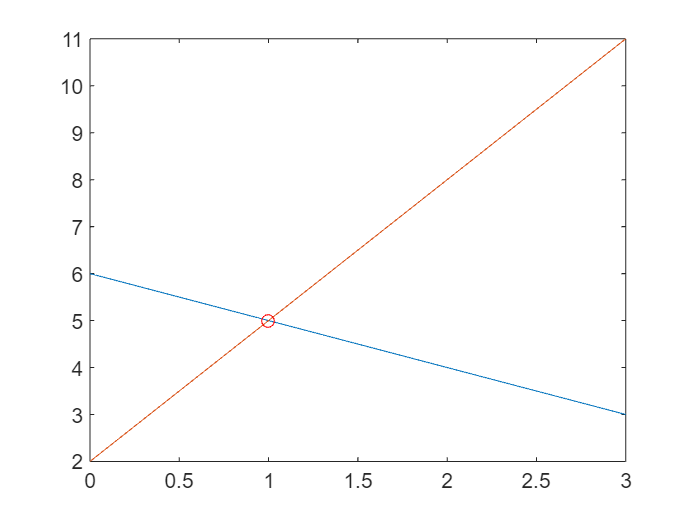

x = point(1);
y = point(2);
hold on
plot(x,y,"ro")
hold off

과결정 시스템 : 변수의 개수 > 방정식의 개수

부족 결정 시스템 : 방정식의 개수 > 변수의 개수

선형 시스템이 부족 결정 시스템이고 무수히 많은 수의 해를 가지고 있는 경우, 백슬래시 연산자는 가장 많은 0 요소를 갖는 해를 반환합니다. 시스템이 과결정 시스템이고 해가 없는 경우, 백슬래시 연산자는 오차의 제곱을 최소로 만드는 "최적의" 벡터를 반환합니다.